File system config and simulation parameter declaration

% File system config
network_fpath = '.\data\MBTA_NoN.xlsx';
network_sname = 'MBTA_stations_XYZ';

% load_from_file = true;

flood_geoTIFF_fpath = "D:\HEC_HMS_Projects\Boston_watersheds_02_30m\RAS\shortPlanID";
flooddata_mat_fname = "Bos_watersheds_30m_02.mat";
floodinfo_mat_fname = "Bos_watersheds_30m_02_info.mat";

% Simulation parameters
threshold = 1/3; % 1/3 meter flood threshold-- standing water depth of more than threshold at time t means a station is flooded 
recov_method = 'betweenness';


Load transit networks and flood simulation output

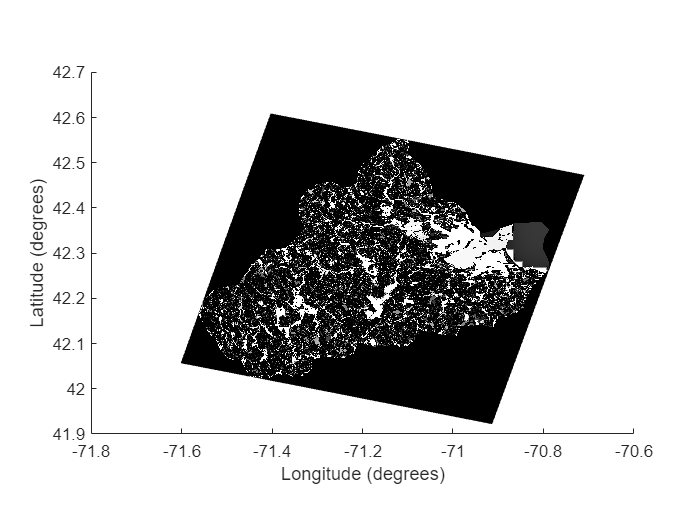

% Load network data
G = read_transit_network(network_fpath, network_sname);

% Load and pre-process GeoTIFF flood data
if load_from_file
    load(flooddata_mat_fname)
    load(floodinfo_mat_fname)
else
    [gA, gR, ginfo] = load_geoTIFF(flood_geoTIFF_fpath);
    [cgA, cgR] = crop_geoTIFF(gA, gR);
    mA = cat(3, cgA{2:end});
end

[glat, glon] = unproject_geoTIFF(cgR);

% Plot single frame of flood map
figure("Name", "Flood map at end of simulation")
geoshow(glat, glon, mA(:,:,end)); hold on
xlabel('Longitude (degrees)')
ylabel('Latitude (degrees)')

Simulate flooding on transit network(s)

slat = G.Nodes.lat;
slon = G.Nodes.lon;
snames = G.Nodes.Name;
%ellipsoid = cgR{end}.ProjectedCRS.GeographicCRS.Spheroid;

% get closes grid cell indices to all station locations
grid_idx = get_closest_gridcell_index(slat, slon, glat, glon);

% check which stations are inundated at each timesteps
flooded_tf = arrayfun(@(xi) check_inundation(grid_idx, mA(2:end,:,xi), threshold),...
    1:size(mA,3), 'UniformOutput', false);

% simulate failure
to_remove = cellfun(@(x) G.Nodes.Name(x), flooded_tf, 'UniformOutput', false);
G_states = cellfun(@(x) rmnode(G, x), to_remove, 'UniformOutput', false);
gcc_states = cellfun(@(g) giant_component_size(g), G_states);

% simulate random null model
rand_ensemble = cell(1000,1);
for i = 1:1000
    G_rand = remove_random_floodcomp(G, to_remove);
    gcc_states_rand = cellfun(@(g) giant_component_size(g), G_rand);
    rand_ensemble{i} = gcc_states_rand;
end
gcc_states_randens = mean(cat(1, rand_ensemble{:}), 1);
stdev_rnd = std(cat(1, rand_ensemble{:}),[],1);
x_rnd = 1:length(stdev_rnd);
std_rnd_x2 = [x_rnd, fliplr(x_rnd)];
std_inBtw = [(gcc_states_randens - (stdev_rnd.*2)), fliplr(gcc_states_randens+(stdev_rnd.*2))];

Visualize failure results

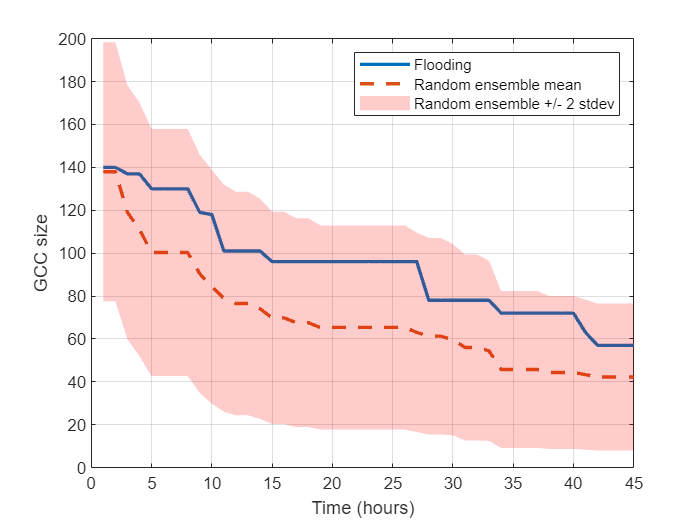

% Failure curve
figure("Name", "Failure curve")
plot(gcc_states, 'LineWidth', 2); hold on; grid on
plot(gcc_states_randens, '--', 'LineWidth', 2)
xlabel('Time (hours)'); ylabel('GCC size')
h = fill(std_rnd_x2, std_inBtw', 'r', 'LineStyle', 'none');
h.FaceAlpha = 0.2; 
legend(["Flooding", "Random ensemble mean", "Random ensemble +/- 2 stdev"])

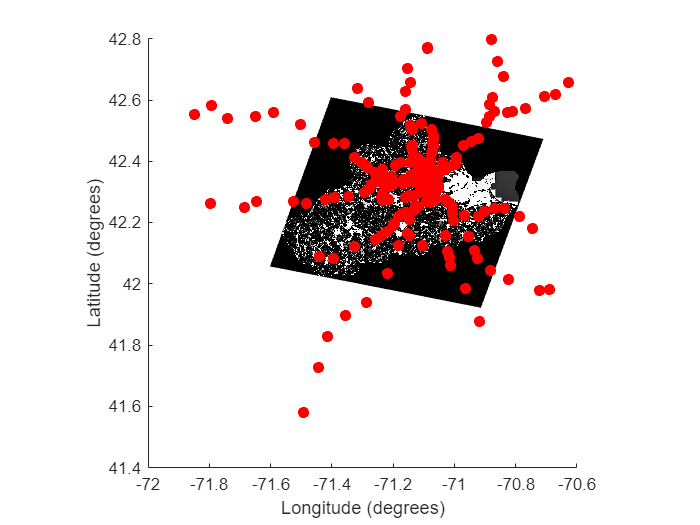


% MBTA network over final flood map at end of simulation
figure("Name", "MBTA network, flood map at end of simulation")
geoshow(glat, glon, mA(:,:,end)); hold on
geoshow(G.Nodes.lat, G.Nodes.lon, 'DisplayType', 'multipoint', 'Marker', '.', 'MarkerSize', 20, 'LineWidth', 2)
xlabel('Longitude (degrees)')
ylabel('Latitude (degrees)')

Simulate recovery

% THIS NEEDS TO BE BUILT
% AAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAA
gcc_states_recov = simulate_recovery(G, G_states{end}, recov_method);


Animate flooding with network superimposed

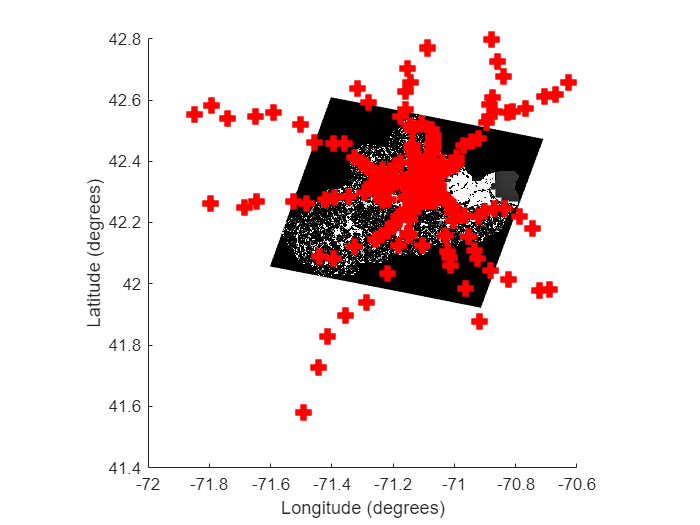

% MBTA network over animated flood timeseries (46 hours, hourly step)
figure("Name", "MBTA network, 46 hours of flooding, 0.292 inches/hour")
geoshow(glat, glon, mA(:,:,end)); hold on
geoshow(G.Nodes.lat, G.Nodes.lon, 'DisplayType', 'multipoint', 'MarkerSize', 10, 'LineWidth', 4)
xlabel('Longitude (degrees)')
ylabel('Latitude (degrees)')

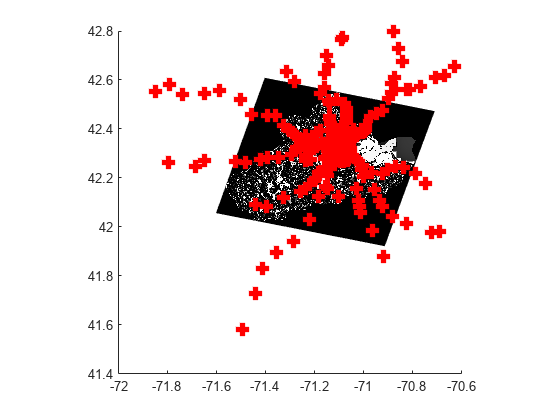

dt = 0.4;
fh = figure();
fh.WindowState = 'maximized';
for i = 1:size(mA,3)
    pause(dt)
    geoshow(glat, glon, mA(:,:,i))
    geoshow(G.Nodes.lat, G.Nodes.lon, 'DisplayType', 'multipoint', 'MarkerSize', 10, 'LineWidth', 4)
end